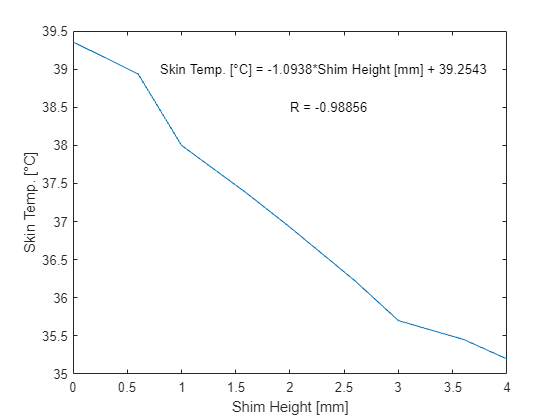

heights = [0 0.6 1 1.6 2 2.6 3 3.6 4]';
power = []';
temperature = [39.357 38.937 38 37.373 36.925 36.221 35.7 35.453 35.197]';
plot(heights, temperature)
ylabel("Skin Temp. ["+char(176)+"C]");
xlabel("Shim Height [mm]")
R = corrcoef(heights,temperature);
text(2, 38.5, "R = "+string(R(1,2)))
p = polyfit(heights, temperature,1);
text(0.8,39,"Skin Temp. ["+char(176)+"C] = "+string(p(1))+"*Shim Height [mm] + "+string(p(2)))